clear all
clc

Q4

% Number of observations
T = 500;
rng(514);

% Generate random noise
epsilon = randn(T,1);  % for y_t
u = randn(T,1);        % for x_t
v = randn(T,1);        % not used, but generated as per instruction

% Generate x_t and y_t as random walks
x = cumsum(u);       % x_t = x_{t-1} + u_t
y = cumsum(epsilon); % y_t = y_{t-1} + epsilon_t

% Create table for fitlm
tbl = table(x, y);

% Fit linear model: y_t ~ x_t
mdl = fitlm(tbl, 'y ~ x');

% Display regression results
disp(mdl);

Linear regression model:
    y ~ 1 + x

Estimated Coefficients:
                   Estimate       SE       tStat       pValue   
                   ________    ________    ______    ___________

    (Intercept)    0.61037      0.21518    2.8366      0.0047462
    x              0.57869     0.017103    33.836    3.5845e-131


Number of observations: 500, Error degrees of freedom: 498
Root Mean Squared Error: 4.02
R-squared: 0.697,  Adjusted R-Squared: 0.696
F-statistic vs. constant model: 1.14e+03, p-value = 3.58e-131


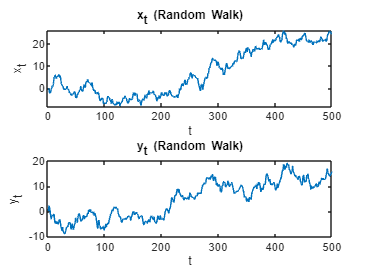


% Plot time series
figure;
subplot(2,1,1);
plot(x);
title('x_t (Random Walk)');
xlabel('t'); ylabel('x_t');

subplot(2,1,2);
plot(y);
title('y_t (Random Walk)');
xlabel('t'); ylabel('y_t');

Interpretation: We find that the coefficient is higly significant so it may be spurious regression. However, since both x_t and y_t are non-stationary (random walks) but not independent, the regression is not spurious.

Q1(a)

% Load the data
data = readtable('realgdpgrowth.xlsx');

% Create transformed variables
data.spread1 = data.GS1 - data.TB3MS;
data.spread2 = data.GS10 - data.TB3MS;
data.corporate = data.BAA - data.AAA;
data.dt3 = data.TB3MS - lagmatrix(data.TB3MS,1);    % first difference
data.dt12 = data.GS1 - lagmatrix(data.GS1,1);     % first difference


Interpretation of Variables:

Spread1 measures the difference between the 1-year and 3-month Treasury bill rates. 

Spread2 measures the difference between the 10-year and 3-month Treasury bill rates. 

Corporate refers to the junk bond spread, which is the difference between the interest rates on low-grade and high-grade corporate bonds. 

dt3 is the quarterly change in the 3-month Treasury rate, calculated as the difference between the current and previous quarter’s 3-month rate. 

dt12 is the quarterly change in the 1-year Treasury rate, calculated as the difference between the current and previous quarter’s 1-year rate

Q1(b)

% maxLag = 3;
% 
% % Restrict sample to 1954Q2–2024Q3
% startDate = datetime(1954,4,1);
% endDate = datetime(2024,9,30);
% data_sub = data(data.date >= startDate & data.date <= endDate, :);
% 
% % Define dependent variable
% gdp = data_sub.gdp;
% 
% % Initialize table to store results
% results = table();
% 
% % Variables to test
% vars = {'dt3', 'dt12', 'spread1', 'spread2', 'corporate'};
% 
% % Loop through each variable to test Granger causality
% for i = 1:length(vars) %1-5
%     x = data_sub.(vars{i});
% 
%     % Run Granger causality test
%     [h, pValue] = gctest(x, gdp,NumLags=3);
%     %[h, pValue] = gctest(combined, 'Lags', maxLag);
% 
%     % Store results
%     results.Variable{i} = vars{i};
%     results.pValue(i) = pValue;
%     results.RejectH0(i) = h;
%     %results.Interpretation{i} = ternary(h, 'Granger-causes GDP', 'Does NOT cause GDP');
% end
% % Show results
% disp(results);
% 
% % seperately
% % Granger causality tests
% [h_dt3,  pValue1] = gctest(data_sub.dt3, data_sub.gdp, 'NumLags', maxLag);
% [h_dt12,  pValue2] = gctest(data_sub.dt12, data_sub.gdp, 'NumLags', maxLag);
% [h_spread1,  pValue3] = gctest(data_sub.spread1, data_sub.gdp, 'NumLags', maxLag);
% [h_spread2,  pValue4] = gctest(data_sub.spread2, data_sub.gdp, 'NumLags', maxLag);
% [h_corp,  pValue5] = gctest(data_sub.corporate, data_sub.gdp, 'NumLags', maxLag);
% 
% fprintf("dt3 → gdp: %d\n", h_dt3,pValue1)
% fprintf("dt12 → gdp: %d\n", h_dt12,pValue2)
% fprintf("spread1 → gdp: %d\n", h_spread1,pValue3)
% fprintf("spread2 → gdp: %d\n", h_spread2,pValue4)
% fprintf("corporate → gdp: %d\n", h_corp,pValue5)

% Or I consider
% table read 
data = readtable('realgdpgrowth.xlsx');

data.spread1 = data.GS1 - data.TB3MS;
data.spread2 = data.GS10 - data.TB3MS;
data.corporate = data.BAA - data.AAA;
data.dt3 = [NaN; diff(data.TB3MS)];
data.dt12 = [NaN; diff(data.GS1)];

% take variables
data = data(:, {'time','gdp','dt3','dt12','spread1','spread2','corporate'});

% choose the range of time
start_idx = find(strcmp(data.time, '1954q2'));
end_idx = find(strcmp(data.time, '2024q3'));
data = data(start_idx:end_idx, :);
data = rmmissing(data);  

% Granger test
T = height(data);
maxlag = 3;
y = data.gdp;

% variables
Xlist = {'dt3','dt12','spread1','spread2','corporate'};

for i = 1:length(Xlist)
    x = data.(Xlist{i});
    
    % model with y lags and intercept
    Y = y(maxlag+1:end);
    Xr = zeros(T - maxlag, maxlag);
    for j = 1:maxlag
        Xr(:, j) = y(maxlag+1-j:end-j);
    end
    Xr = [ones(size(Xr,1),1), Xr];  

    
    Xur = zeros(T - maxlag, 2 * maxlag);
    for j = 1:maxlag
        Xur(:, j) = y(maxlag+1-j:end-j);
        Xur(:, j + maxlag) = x(maxlag+1-j:end-j);
    end
    Xur = [ones(size(Xur,1),1), Xur];  

    % calculate RSS
    e_r = Y - Xr * (Xr \ Y);
    RSSr = sum(e_r.^2);
    e_ur = Y - Xur * (Xur \ Y);
    RSSur = sum(e_ur.^2);

    q = maxlag;                  
    k = 2 * maxlag + 1;          
    df2 = T - maxlag - k;        

    % F test
    Fstat = ((RSSr - RSSur) / q) / (RSSur / df2);
    pval = 1 - fcdf(Fstat, q, df2);

    fprintf('Granger causality test:' , Xlist{i});
    fprintf('F-stat = %.4f, p-value = %.4f\n\n', Fstat, pval);
end

Granger causality test:

F-stat = 2.5872, p-value = 0.0534



Granger causality test:

F-stat = 3.2960, p-value = 0.0210



Granger causality test:

F-stat = 1.6910, p-value = 0.1692



Granger causality test:

F-stat = 2.5421, p-value = 0.0567



Granger causality test:

F-stat = 3.3993, p-value = 0.0183



Interpretation: The results show that both the 1-year interest rate change (dt12) and the corporate credit spread (corporate) significantly predict GDP growth at the 5% level. The 3-month rate (dt3) and the long-term yield curve (spread2) are marginally significant at the 10% level, while the short-term yield curve (spread1) shows no significant effect. These findings are consistent with economic theory: interest rate changes signal monetary policy shifts, and credit spreads reflect market expectations about future conditions and default risks. In particular, corporate spreads widen in downturns, making them a useful leading indicator.

Q1(c)

I would select the corporate for forecasting the futrue GDP because it is the most significant with least p-value. You may also involve dt12 in model since it is also statistically significant. For (d), I will use the most significant variable, the corperate. 

Q1(d)

% MATLAB Code for Question 1(d) - GDP Forecast using Corporate Spread

% Load the Excel file
data = readtable('realgdpgrowth.xlsx');

% Create the corporate spread variable
data.corporate = data.BAA - data.AAA;

% Filter the data to the required date range (1954q2-2024q3)
% Assuming 'date' is in datetime format or there's a quarter column
startDate = datetime(1954, 4, 1); % 1954q2
endDate = datetime(2024, 9, 30);  % 2024q3
data = data(data.date >= startDate & data.date <= endDate, :);

% Create lagged variables for GDP and corporate spread
n = height(data);
gdp = data.gdp;
corporate = data.corporate;

% Create lags (3 lags as specified in the problem)
gdp_lag1 = [NaN; gdp(1:n-1)];
gdp_lag2 = [NaN; NaN; gdp(1:n-2)];
gdp_lag3 = [NaN; NaN; NaN; gdp(1:n-3)];

corp_lag1 = [NaN; corporate(1:n-1)];
corp_lag2 = [NaN; NaN; corporate(1:n-2)];
corp_lag3 = [NaN; NaN; NaN; corporate(1:n-3)];

% Create a table with the variables for regression
regressionTable = table(gdp, gdp_lag1, gdp_lag2, gdp_lag3, corporate, corp_lag1, corp_lag2, corp_lag3);

% Remove NaN values (first 3 rows will have NaNs due to lags)
regressionTable = regressionTable(4:end, :);

% Build the VAR model (GDP and corporate spread with 3 lags)
% We're using GDP and corporate spread as endogenous variables
% Format data for VAR estimation
Y = [regressionTable.gdp, regressionTable.corporate];
X = [ones(height(regressionTable), 1), ...
     regressionTable.gdp_lag1, regressionTable.gdp_lag2, regressionTable.gdp_lag3, ...
     regressionTable.corp_lag1, regressionTable.corp_lag2, regressionTable.corp_lag3];

% Estimate the VAR model by OLS
beta = (X' * X) \ (X' * Y);

% Get residuals
residuals = Y - X * beta;

% Compute variance-covariance matrix of residuals
Sigma = (residuals' * residuals) / (size(residuals, 1) - size(X, 2));

% Last known values for forecasting
lastValues = regressionTable(end, :);

% Now, forecast for 2024Q4, 2025Q1-Q3 (4 quarters)
numPeriods = 4;
forecasts = zeros(numPeriods, 2);
forecast_lower = zeros(numPeriods, 1);
forecast_upper = zeros(numPeriods, 1);

% Point forecasts
for t = 1:numPeriods
    if t == 1
        % For the first forecast period, use the last known values
        x_t = [1, lastValues.gdp, lastValues.gdp_lag1, lastValues.gdp_lag2, ...
               lastValues.corporate, lastValues.corp_lag1, lastValues.corp_lag2];
    elseif t == 2
        % For the second forecast period
        x_t = [1, forecasts(1,1), lastValues.gdp, lastValues.gdp_lag1, ...
               forecasts(1,2), lastValues.corporate, lastValues.corp_lag1];
    elseif t == 3
        % For the third forecast period
        x_t = [1, forecasts(2,1), forecasts(1,1), lastValues.gdp, ...
               forecasts(2,2), forecasts(1,2), lastValues.corporate];
    else
        % For the fourth forecast period
        x_t = [1, forecasts(3,1), forecasts(2,1), forecasts(1,1), ...
               forecasts(3,2), forecasts(2,2), forecasts(1,2)];
    end
    
    % Calculate point forecast
    forecasts(t,:) = x_t * beta;
    
    % Calculate forecast standard error for GDP (increases with forecast horizon)
    % This is a simplified approach - in practice, the formula is more complex
    forecast_se = sqrt(Sigma(1,1) * (1 + t*0.1)); % Increasing SE with horizon
    
    % 95% confidence interval (using 1.96 for 95% CI)
    forecast_lower(t) = forecasts(t,1) - 1.96 * forecast_se;
    forecast_upper(t) = forecasts(t,1) + 1.96 * forecast_se;
end

% Create a table with the forecasts
quarters = {'2024Q4', '2025Q1', '2025Q2', '2025Q3'};
forecastTable = table(quarters', forecasts(:,1), forecast_lower, forecast_upper, ...
                     'VariableNames', {'Quarter', 'GDP_Growth', 'Lower_95', 'Upper_95'});

% Display the forecasts
disp('GDP Growth Forecasts based on Corporate Spread Model:');

GDP Growth Forecasts based on Corporate Spread Model:


disp(forecastTable);

     Quarter      GDP_Growth    Lower_95    Upper_95
    __________    __________    ________    ________

    {'2024Q4'}      3.1721       -5.728      12.072 
    {'2025Q1'}      3.0762      -6.2197      12.372 
    {'2025Q2'}      3.0884      -6.5871      12.764 
    {'2025Q3'}      3.0911      -6.9496      13.132 



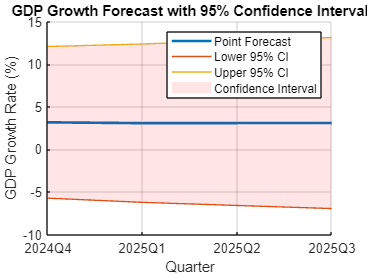


% Plot the forecasts with confidence intervals
figure;
hold on;
plot(1:numPeriods, forecasts(:,1),  'LineWidth', 2);
plot(1:numPeriods, forecast_lower,  'LineWidth', 1);
plot(1:numPeriods, forecast_upper, 'LineWidth', 1);
fill([1:numPeriods, fliplr(1:numPeriods)], ...
     [forecast_lower', fliplr(forecast_upper')], ...
     'r', 'FaceAlpha', 0.1, 'EdgeColor', 'none');
xticks(1:numPeriods);
xticklabels(quarters);
xlabel('Quarter');
ylabel('GDP Growth Rate (%)');
title('GDP Growth Forecast with 95% Confidence Interval');
grid on;
legend('Point Forecast', 'Lower 95% CI', 'Upper 95% CI', 'Confidence Interval');
hold off;

Q2

% Extract the series
data1 = readtable('AAA.xlsx','Sheet',2); 
data2 = readtable('BAA.xlsx','Sheet',2);
AAA = data1.AAA;
BAA = data2.BAA;
spread = BAA - AAA;

% ADF Test: Null is that the series has a unit root (i.e. non-stationary)
[h_AAA, p_AAA, stat_AAA, cValue_AAA] =adftest(AAA,Model="ARD",lags=12);
[h_BAA, p_BAA, stat_BAA, cValue_BAA] = adftest(BAA,Model="ARD",lags=12);
[h_spread, p_spread, stat_spread, cValue_spread] = adftest(spread,Model="ARD",lags=12);

% Display results
fprintf('ADF Test Results:\n');

ADF Test Results:


fprintf('AAA Bond Yield:     H = %d, p-value = %.4f\n', h_AAA, p_AAA);

AAA Bond Yield:     H = 0, p-value = 0.4172


fprintf('BAA Bond Yield:     H = %d, p-value = %.4f\n', h_BAA, p_BAA);

BAA Bond Yield:     H = 0, p-value = 0.1928


fprintf('BAA - AAA Spread:   H = %d, p-value = %.4f\n', h_spread, p_spread);

BAA - AAA Spread:   H = 1, p-value = 0.0010


By ADF test, we find that there are likely unit roots in AAA and BAA but no unit root in the spread.